# **ACM 11 Homework 3, Part 2/2: Optimization with the Rosenbrock function**

## **Instructions**

This assignment is **due Friday, May 7, 11:59pm Pacific Time**. This is the second of two parts of HW 3, and can be completed after Week 5 of class. Follow the instructions in this file to complete the provided skeleton optimization functions, and call the functions in this file. Code to plot your results has been provided for you. Answer the accompanying questions in complete sentences. 

## **Rosenbrock function**: Introduction

The Rosenbrock function, given below, is a popular test function for developing optimization algorithms. It is sometimes known as the banana function, because it has a banana-shaped valley, as you will see from running the provided plotting code.


$$f(x,y)=(1-x)^2+(y-x^2)^2$$


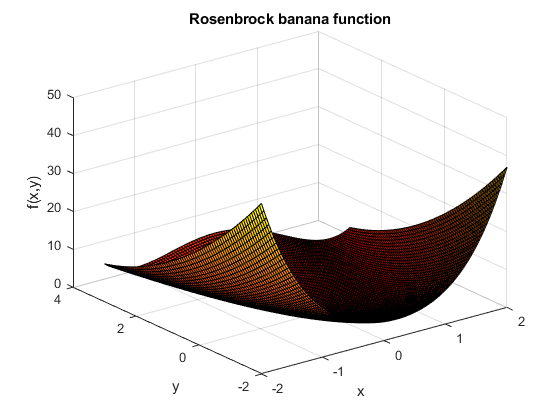

clear
close all

xplt = linspace(-2,2,100);
yplt = linspace(-2,3,80)';
fplt = (1-xplt).^2 + (yplt-xplt.^2).^2;

figure(1); clf
surf(xplt,yplt,fplt); colormap autumn
xlabel('x')
ylabel('y')
zlabel('f(x,y)')
title('Rosenbrock banana function')

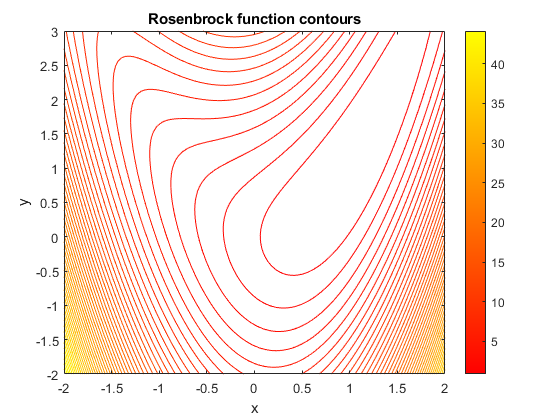


figure(2); clf
num_contours = 50;
contour(xplt,yplt,fplt,num_contours); colormap autumn
colorbar
xlabel('x')
ylabel('y')
title('Rosenbrock function contours')

What makes this function an interesting test case for optimization is that the valley is relatively large and most optimization algorithms can find the valley very easily. Within the valley, however, the function is nearly flat, making it difficult for optimization algorithms to find the true minimum robustly.  The true minimum can be found quite easily analytically, in this case the minimum is $(x,y)=(1,1)$. In this exercise, you will implement the steepest descent and Newton optimization methods with a simple line search to find the minimum of the Rosenbrock function.

## Problem 3: Rosenbrock function, gradient, and Hessian

Direct calculation shows that the gradient $\mathbf{g} = \nabla f$ and the Hessian $\mathbf{H}$ admit closed form solutions:

$\mathbf{g}=\pmatrix{-2(1-x)-4x(y-x^2) \cr
2(y-x^2)}$，$\mathbf{H}=\pmatrix{2-4y+12x^2 & -4x \cr -4x & 2}$.

The provided skeleton code file, r`osenbrock.m`, uses the inputs $x$ and $y$ and outputs the Rosenbrock value$f(x, y)$. Please complete this file to also output the gradient and Hessian (matrix of second derivatives) of the Rosenbrock function. The gradient $\mathbf{g}$ at $(x, y)$ should be a column vector of size $2\times 1$. The Hessian $\mathbf{H}$ at $(x, y)$ should be a matrix of size $2\times 2$.

## **Problem 4: Implementing the Gradient Descent**

Now we implement the gradient descent method. The gradient descent method starts at some point $(x_0, y_0)$, and iteratively updates our current guess of the optimal point for the Rosenbrock function. At iteration $n$, for $n=1,2,3, \ldots$, it updates


$$\pmatrix{x_{n} \cr y_{n}}=\pmatrix{x_{n-1} \cr y_{n-1}}-\alpha_n\mathbf{g}_{n-1}$$


where $\mathbf{g}_{n-1}$ is the gradient at $(x_{n-1}, y_{n-1})$, and $\alpha_n$ is the scalar called the step size. The iteration is stopped when we find the gradient is small enough, i.e. we stop at iteration $n$ when $\|\mathbf{g}_{n}\|_2<\varepsilon$ for some pre-selected constant $\varepsilon$. To make the algorithm more robust, we usually set an upper bound for the number of iteration $N_{max}$. After iteration $N_{max}$ (if we really need to get there), we will quit the iteration anyway.

**Problem 4a: Gradient Descent with Fixed Stepsize**

We first use a fixed step size $\alpha_n=\alpha$. Complete the provided skeleton code file, `Rosenbrock_gd_fixed.m`, which takes the initial point $x_0$ and $y_0$, step size $\alpha$, the tolerance $\varepsilon$, and maximum number of iteration $N_{max}$ as the inputs. Suppose the iteration stops at iteration $N$. The provided function should output (i) a $2\times (N+1)$ matrix containing the optimization path (the $i$-th column stores $(x_{i-1}, y_{i-1})$, and (ii) a $1\times(N+1)$vector containing the convergence path (the $i$-th term stores $f(x_{i-1}, y_{i-1})$). Note that the optimal (x,y) should be the last column of the optimization path and the optimal function value is the last entry of the convergence path.

Now run the code below to call your gradient descent function with initial condition $(x_0, y_0)=(-0.5, 2)$ and set the tolerance $\varepsilon$ to be $10^{-5}$. Choose a fixed step size $\alpha$ such that the method converges in less than 300 iterations (Hint: Keep $\alpha$ less than 0.2). Code to plot your results is provided for you, as well as a print out of how many iterations are needed to converge.

Nmax = 300;
x0 = -0.5;
y0 = 2;
epsilon = 1e-5;

% put your choice of alpha here
alpha = 0.1;

% call your gradient descent with fixed stepsize
[opt_path, conv_path] = Rosenbrock_gd_fixed(x0, y0, alpha, epsilon, Nmax);
x_opt = opt_path(1,end);
y_opt = opt_path(2,end);

[f_opt,g_opt] = rosenbrock(x_opt,y_opt);

% report your number of iteration used
fprintf(['Number of iteration used: ', num2str(length(conv_path)-1)])

Number of iteration used: 293

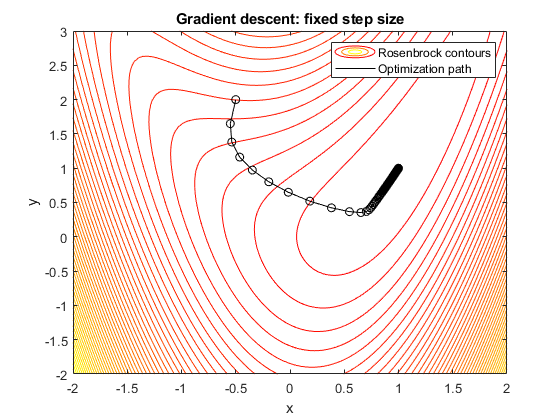


% plot the optimziation path and the convergence path
figure(3); clf
contour(xplt,yplt,fplt,num_contours); hold on; colormap autumn
plot(opt_path(1,:), opt_path(2,:),'k'); hold on
plot(opt_path(1,:),opt_path(2,:),'ko')
xlabel('x')
ylabel('y')
legend('Rosenbrock contours','Optimization path')
title('Gradient descent: fixed step size')

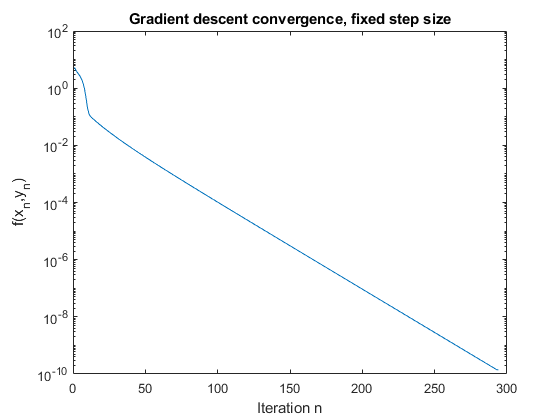


figure(4); clf
semilogy(conv_path)
xlabel('Iteration n')
ylabel('f(x_n,y_n)')
title('Gradient descent convergence, fixed step size')

**Problem 4b: Discussion**

How many iterations does it take your fixed-step gradient descent algorithm to find lowest contour in the contour plot of the Rosenbrock valley? How many more iterations does it take to converge within the region defined by the lowest contour? In 1-2 sentences, describe why the algorithm needs so many iterations in this area.

fprintf(['4b: It takes 8 iterations to find the lowest contour but 285 iterations to \n ' ...
    'converge within the region. It takes this long because we are using a fixed \n' ...
    'step size, so as we get closer and the gradient decreases, the steps become \n' ...
    'smaller and smaller.'])

4b: It takes 8 iterations to find the lowest contour but 285 iterations to 
 converge within the region. It takes this long because we are using a fixed 
step size, so as we get closer and the gradient decreases, the steps become 
smaller and smaller.

**Problem 4c: Gradient Descent with Bisection Search**

One improvement of the previous algorithm is to determine the step size $\alpha_n$ by a bisection line search. This finds the optimal step size to take along the descent direction as follows: given the most recent guess, $\left(x_{n-1} ,y_{n-1} \right)$, and the corresponding normalized gradient at that guess, $\hat{\mathbf{g}}={\mathbf{g}}_{n-1}/\|\mathbf{g}_{n-1}\|_2$, we want to take a step of size $\alpha$ in the direction of descent, i.e., the next guess will be

$\pmatrix{x_n \cr y_n}=\pmatrix{x_{n-1} \cr y_{n-1}}-\alpha \hat \mathbf{g} \qquad (*)$.

The function value at our next guess is $f\left(x_n ,y_n \right)$. Since the next guess depends on $\alpha$, we would like to find the step size that minimizes the function value at our next guess. Using the chain rule, we can write:

$p(\alpha):=\frac{\text{d}f(x_n,y_n)}{\text{d}\alpha} = \nabla f(x_n,y_n)\cdot \pmatrix{ \frac{\text{d}x_n}{\text{d}\alpha} \cr \frac{\text{d}y_n}{\text{d}\alpha}} =  \pmatrix{ g_1(x_n,y_n) \cr g_2(x_n,y_n)} \cdot-\hat{\mathbf{g}}$,

where $g_1 \left(x_n ,y_n \right)$ and $g_2 \left(x_n ,y_n \right)$ are the components of the gradient at $\left(x_n {,y}_n \right)$ with the step size $\alpha$ as defined in $\left(*\right)$. We want to set this to 0 to find an $\alpha$ that minimizes $f$ in the direction of $\hat{g} \ldotp$ 

In the provided skeleton code file, `Rosenbrock_gd_bisec.m`, implement gradient descent, this time using a bisection line search to find the best $\alpha$ at each step. To do this, at each iteration you should define a function $p\left(\alpha \right)$ as defined above, and then call the provided bisection routine to find a root where $p\left(\alpha \right)=0\ldotp$ For the bisection search, you should use an initial interval of [0,$\alpha_{\textrm{UB}}$], a convergence tolerance $\tau=10^{-10}$, and a maximum iteration count of $n_{max}=40$.

As before, call your completed function that runs gradient descent with bisection line search. Use the same initial condition as before, $(x_0, y_0)=(-0.5, 2)$ and set the tolerance $\varepsilon$ to be $10^{-5}$. For the line search, we have provided $\alpha_{\textrm{UB}} =3$. As before, the code to print and plot your results is provided for you.

Nmax = 300;
x0 = -0.5;
y0 = 2;
epsilon = 1e-5;
alpha_UB = 3;   % upper bound for line search

% call your gradient descent with fixed stepsize
[opt_path, conv_path] = Rosenbrock_gd_bisec(x0, y0, alpha_UB, epsilon, Nmax);
x_opt = opt_path(1,end);
y_opt = opt_path(2,end);

[f_opt,g_opt] = rosenbrock(x_opt,y_opt);

% report your number of iteration used
fprintf(['Number of iteration used: ', num2str(length(conv_path)-1)])

Number of iteration used: 49

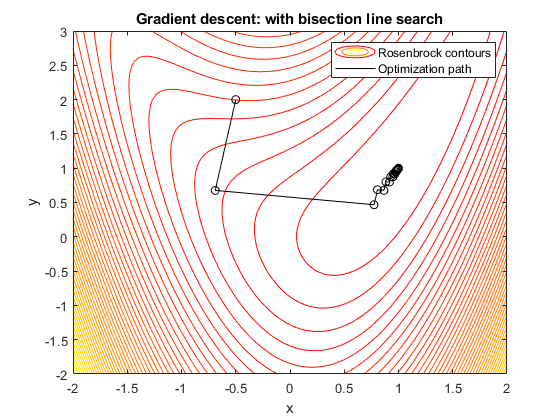


% plot the optimziation path and the convergence path
figure(5); clf
contour(xplt,yplt,fplt,num_contours); hold on; colormap autumn
plot(opt_path(1,:), opt_path(2,:),'k'); hold on
plot(opt_path(1,:),opt_path(2,:),'ko')
xlabel('x')
ylabel('y')
legend('Rosenbrock contours','Optimization path')
title('Gradient descent: with bisection line search')

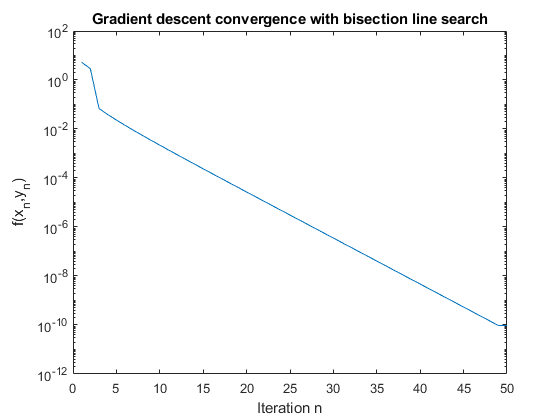


figure(6); clf
semilogy(conv_path)
xlabel('Iteration n')
ylabel('f(x_n,y_n)')
title('Gradient descent convergence with bisection line search')

**Problem 4d: Discussion**

Compare your results for 4c with your results for 4a. How are the optimization paths different? Which algorithm converges in fewer iterations? What is the price we pay in that algorithm to get the faster convergence?

fprintf(['4d: 4c converges quicker with larger jumps, but this comes at the cost of \n' ...
    'a more expensive computation for each jump from finding the optimal step size.'])

4d: 4c converges quicker with larger jumps, but this comes at the cost of 
a more expensive computation for each jump from finding the optimal step size.

## **Problem 5: Implementing Newton's method**

Now we implement Newton's method for optimization. Newton's method starts at some point $(x_0, y_0)$, and iteratively updates our current guess of the optimal point for the Rosenbrock function. At iteration $n$, for $n=1,2,3, \ldots$, it updates


$$\pmatrix{x_{n} \cr y_{n}}=\pmatrix{x_{n-1} \cr y_{n-1}}-\alpha_n\mathbf{H}_{n-1}^{-1}\mathbf{g}_{n-1}$$


where $\mathbf{g}_{n-1}$ is the gradient at $(x_{n-1}, y_{n-1})$, $\mathbf{H}_{n-1}$ is the Hessian at $(x_{n-1}, y_{n-1})$ and $\alpha_n$ is the stepsize. The iteration is stopped when we find the gradient is small enough, i.e. we stop at iteration $n$ when $\|\mathbf{g}_{n}\|_2<\varepsilon$ for some pre-selected constant $\varepsilon$, or the iteration number $n$ reaches the pre-selected upper bound $N_{max}$.

**Problem 5a: Newton's method with Fixed Stepsize**

We first use a fixed step size $\alpha_n=\alpha$. Complete the provided skeleton code file, `Rosenbrock_newton_fixed.m`, which takes the initial point $x_0$ and $y_0$, the fixed stepsize $\alpha$ the tolerance $\varepsilon$, and maximum number of iterations $N_{max}$ as the inputs. It is expected to output  a $2\times (N+1)$ matrix encoding the optimization path (the $i$-th column stores $(x_{i-1}, y_{i-1})$, and a $1\times(N+1)$vector encoding the convergence path (the $i$-th term stores $f(x_{i-1}, y_{i-1})$), where $N$ is the number of iterations needed to converge.

As before, call your completed routine with $(x_0, y_0)=(-0.5, 2)$, using step size $\alpha =1$, and tolerance $\varepsilon=10^{-5}$. Code to plot and print your results is provided for you.

Nmax = 300;
x0 = -0.5;
y0 = 2;
alpha = 1;
epsilon = 1e-5;

% call your gradient descent with fixed stepsize
[opt_path, conv_path] = Rosenbrock_newton_fixed(x0, y0, alpha, epsilon, Nmax);
x_opt = opt_path(1,end);
y_opt = opt_path(2,end);

[f_opt,g_opt] = rosenbrock(x_opt,y_opt);

% report your number of iteration used
fprintf(['Number of iteration used: ', num2str(length(conv_path)-1)])

Number of iteration used: 8

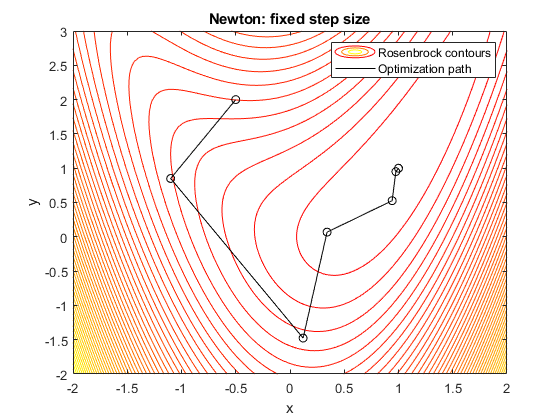


% plot the optimziation path and the convergence path
figure(7); clf
contour(xplt,yplt,fplt,num_contours); hold on; colormap autumn
plot(opt_path(1,:), opt_path(2,:),'k'); hold on
plot(opt_path(1,:),opt_path(2,:),'ko')
xlabel('x')
ylabel('y')
legend('Rosenbrock contours','Optimization path')
title('Newton: fixed step size')

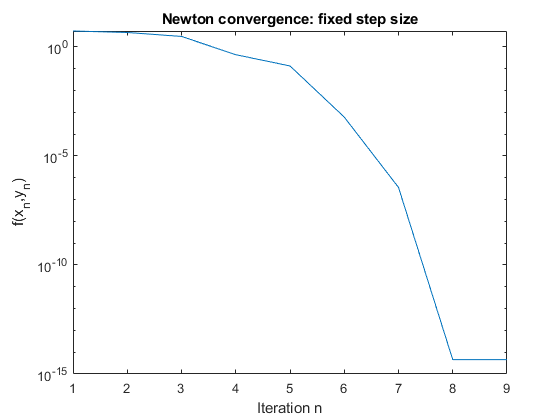


figure(8); clf
semilogy(conv_path)
xlabel('Iteration n')
ylabel('f(x_n,y_n)')
title('Newton convergence: fixed step size')

**Problem 5b: Discussion**

Compare the results of 5a (Newton fixed step size) with 4a (Gradient descent fixed step size). Which algorithm converges in fewer iterations? What is the price we pay to get that faster convergence?

fprintf(['5b: The Newton converges quicker at the price of more computationally expensive \n' ...
    'calculations for each jump from calculating the Hessian.'])

5b: The Newton converges quicker at the price of more computationally expensive 
calculations for each jump from calculating the Hessian.

**Problem 5c: Newton's method with Bisection Search**

Similarly to Problem 4c, we may also do the bisection line search for $\alpha_n$ in the Newton's method. But in Newton's method, the direction of the step we take is given by $\hat \mathbf{g}=\mathbf{H}_{n-1}^{-1}\mathbf{g}_{n-1}/\|\mathbf{H}_{n-1}^{-1}\mathbf{g}_{n-1}\|_2$, and the function $q\left(\alpha \right)$ that we want to find a root of is given by

$q(\alpha): = - \pmatrix{ g_1(x_n,y_n) \cr g_2(x_n,y_n)}^\top\mathbf{H}_n^{-1}\hat{\mathbf{g}}$.

We omit the derivation of the above equation here, but it follows similar logic to the derivation in the gradient descent case. As in 4c, complete the provided skeleton code file, `Rosenbrock_newton_bisec.m`, with Newton's method, using the provided line search to find a step size $\alpha$ that is a root of $q\left(\alpha \right)$. Use the same bisection search parameters as in Problem 4c. Once we find the right step size, the update is:


$$\pmatrix{x_n \cr y_n}=\pmatrix{x_{n-1} \cr y_{n-1}}-\alpha \hat \mathbf{g},$$


with $\hat{\mathit{\mathbf{g}}}$ defined using the Hessian as above.

Again, now start with $(x_0, y_0)=(-0.5, 2)$ and set the tolerance $\varepsilon$ to be $10^{-5}$. Code to plot and print your results has been provided for you.

Nmax = 300;
x0 = -0.5;
y0 = 2;
alpha_UB = 3;
epsilon = 1e-5;

% call your gradient descent with fixed stepsize
[opt_path, conv_path] = Rosenbrock_newton_bisec(x0, y0, alpha_UB, epsilon, Nmax);
x_opt = opt_path(1,end);
y_opt = opt_path(2,end);

[f_opt,g_opt] = rosenbrock(x_opt,y_opt);

% report your number of iteration used, and if the stopping criterion is satisfied
fprintf(['Number of iteration used: ', num2str(length(conv_path)-1)])

Number of iteration used: 6

if norm(g_opt) < epsilon
    fprintf('The stopping criterion is satisfied.')
else
    fprintf('The stopping criterion is not satisfied.')
end

The stopping criterion is satisfied.

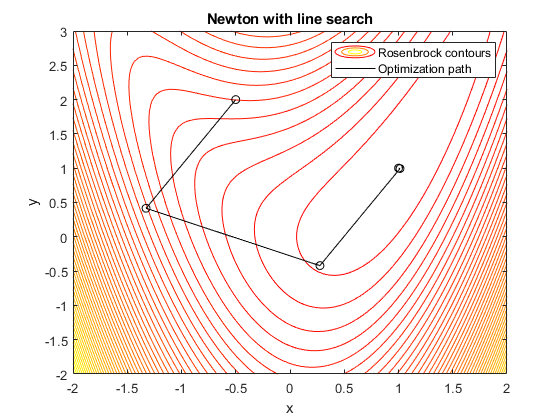


% plot the optimziation path and the convergence path
figure(9); clf
contour(xplt,yplt,fplt,num_contours); hold on; colormap autumn
plot(opt_path(1,:), opt_path(2,:),'k'); hold on
plot(opt_path(1,:),opt_path(2,:),'ko')
xlabel('x')
ylabel('y')
legend('Rosenbrock contours','Optimization path')
title('Newton with line search')

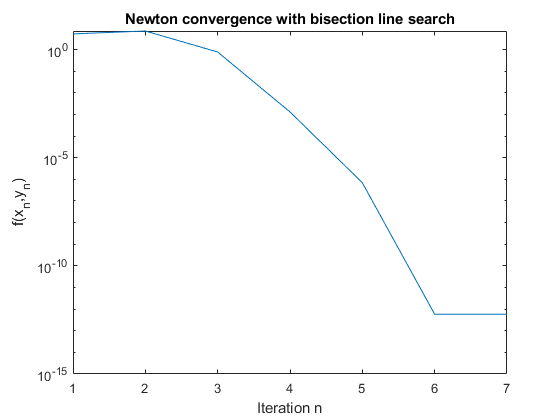


figure(10); clf
semilogy(conv_path)
xlabel('Iteration n')
ylabel('f(x_n,y_n)')
title('Newton convergence with bisection line search')

**Problem 5d: Discussion**

Compare the results of 5c (Newton with bisection) with 5a (Newton fixed step size) and 4c (Gradient descent with bisection). Which algorithm converges in the fewest iterations? What are the prices we pay to get that fastest convergence?

fprintf(['5d: 5c converges quicker than 5a, but we pay the price of even more \n' ...
    'computationally expensive jumps from both calculating the Hessian as well as \n' ...
    'finding the optimal step size.'])

5d: 5c converges quicker than 5a, but we pay the price of even more 
computationally expensive jumps from both calculating the Hessian as well as 
finding the optimal step size.